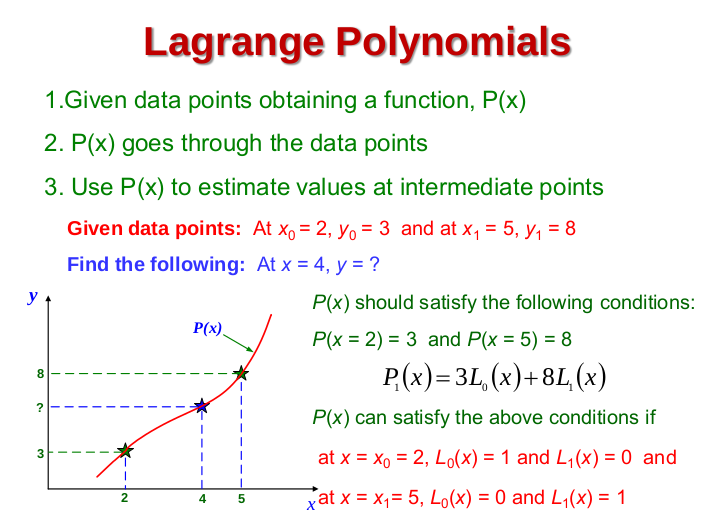

clear all;
x = [2 5]; 
y = [3 8];
yi = LagrangeInterp(x,y,4)

yi =    6.333333333333333


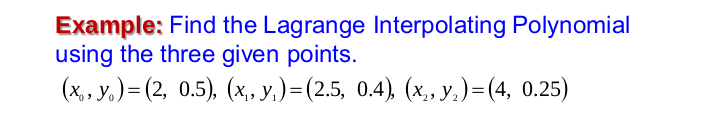

x = [2 2.5 4]; 
y = [0.5 .4 .25];
yi = LagrangeInterp(x,y,3)

yi =    0.325000000000000


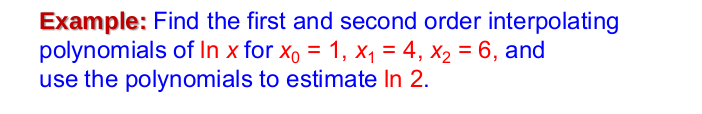

x=[1 4 6]

x =      1     4     6


y=ln(x)

y =                    0   1.386294361119891   1.791759469228055


y =                    0   1.386294361119891   1.791759469228055


LagrangeInterp(x,y,2)

ans =    0.565844346900983


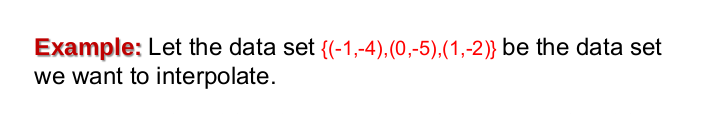

x = [-1 0 1]

x =     -1     0     1


y = [-4 -5 -2]

y =     -4    -5    -2


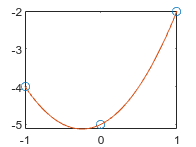

a2 =    1.999999999999999


a1 =      1


a0 =   -4.999999999999999


[a2, a1, a0] = QuadraticRegression(x,y)

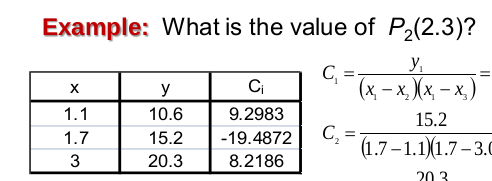

x = [1.1 1.7 3]

x =    1.100000000000000   1.700000000000000   3.000000000000000


y = [10.6 15.2 20.3]

y =   10.600000000000000  15.199999999999999  20.300000000000001


LagrangeInterp(x,y,2.3)

ans =   18.381376518218623


x=[1 4 6 5]

x =      1     4     6     5


y=ln(x)

y =                    0   1.386294361119891   1.791759469228055   1.609437912434100


y =                    0   1.386294361119891   1.791759469228055   1.609437912434100


LagrangeInterp(x,y,2)

ans =    0.628768578908414


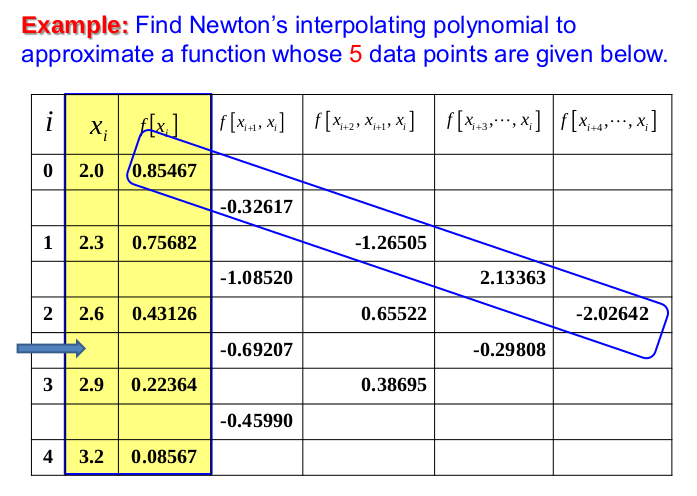

x = [2 2.3 2.6 2.9 3.2];
y = [0.85467 0.75682 0.43126 0.22364 0.0567];
yi = NewtonInterp(x,y,2.8)

yi =    0.275809506172840


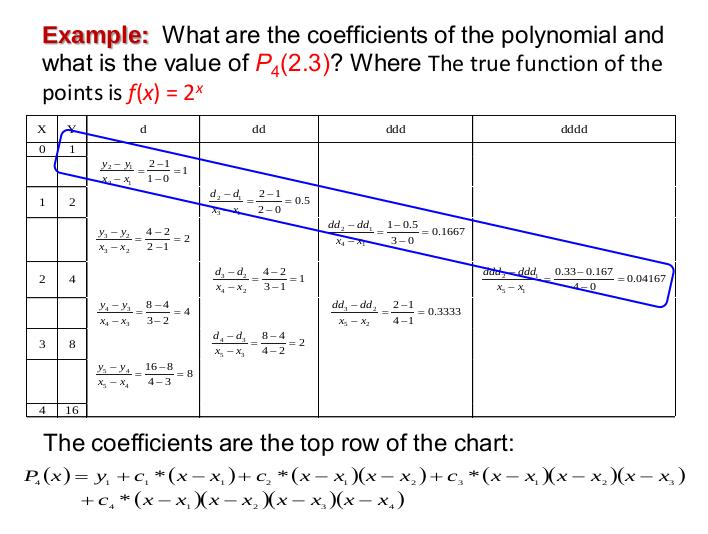

x = [0 1 2 3 4];
y = 2.^x;
LagrangeInterp(x,y,2.3)

ans =    4.918337500000000


NewtonInterp(x,y,2.3)

ans =    4.918337500000000


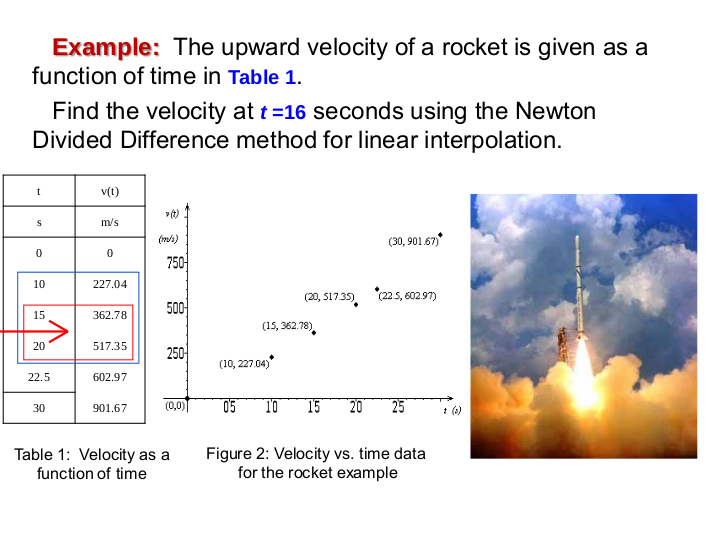

clear;clc;clf

t = [0 10 15 20 22.5 30]

t =                    0  10.000000000000000  15.000000000000000  20.000000000000000  22.500000000000000  30.000000000000000


vt = [0 227.04 362.78 517.35 602.97 901.67]

vt = 1.0e+02 *

                   0   2.270400000000000   3.627800000000000   5.173500000000001   6.029700000000000   9.016700000000000


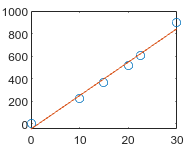

a1 =   29.685234285714273


a0 =  -47.083390476190189


[a1, a0] = LinearRegression(t,vt)

n=16;
(a1*n+a0)

ans =      4.278803580952382e+02


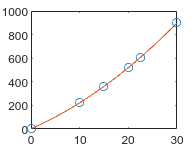

a2 =    0.396288494208498


a1 =   17.994723706563590


a0 =    2.122430888031476



clf
[a2, a1, a0] = QuadraticRegression(t,vt)

(a2*n^2+a1*n+a0)

ans =      3.914878647104244e+02


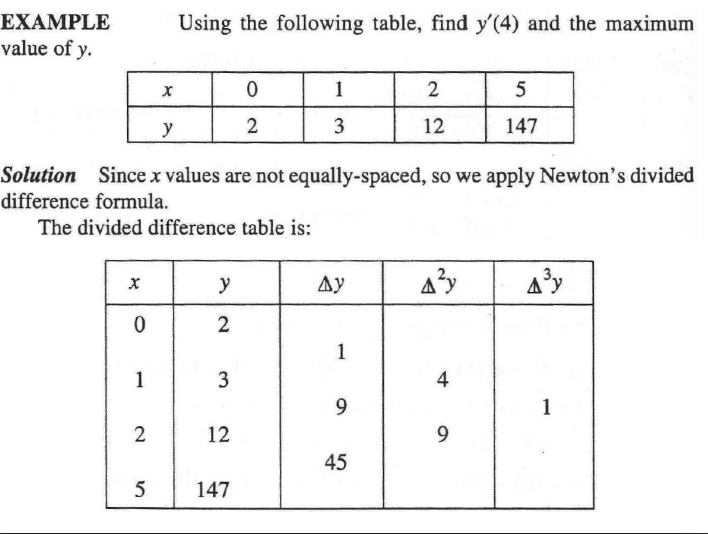

clf;clear;clc
x = [0 1 2 5]

x =      0     1     2     5


y = [2 3 12 147]

y =      2     3    12   147



% two point backward 
% version1
for(i=1:3)
    dy(i) = (y(i+1)-y(i))/(x(i+1)-x(i));
end

for(i=1:2)
    ddy(i) = (dy(i+1)-dy(i))/(x(i+2)-x(i));
end

for(i=1:1)
    dddy(i) = (ddy(i+1)-ddy(i))/(x(i+3)-x(i));
end
% version2
[tbl,yi] = Dividediff(x,y,1.5)

tbl =      0     2     1     4     1
     1     3     9     9     0
     2    12    45     0     0
     5   147     0     0     0


yi =    6.125000000000000



syms X
f = y(1)+(X-x(1))*(dy(1))+(X-x(1))*(X-x(2))*(ddy(1))+(X-x(1))*(X-x(2))*(X-x(3))*(dddy(1))

$$f = X+4\,X\,\left(X-1\right)+X\,\left(X-1\right)\,\left(X-2\right)+2$$

subs(diff(f),X,4)

$$ans = 55$$

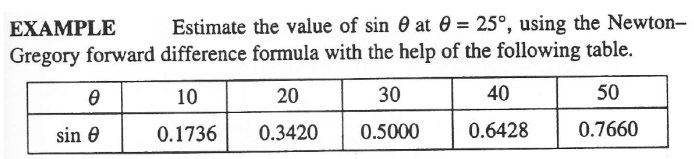

clf;clear;
x = [10 20 30 40 50]

x =     10    20    30    40    50


y = [0.1736 0.3420 0.5000 0.6428 0.7660]

y =    0.173600000000000   0.342000000000000   0.500000000000000   0.642800000000000   0.766000000000000


[tbl,yi] = Dividediff(x,y,25)

tbl =   10.000000000000000   0.173600000000000   0.016840000000000  -0.000052000000000  -0.000000800000000   0.000000001666667
  20.000000000000000   0.342000000000000   0.015800000000000  -0.000076000000000  -0.000000733333333                   0
  30.000000000000000   0.500000000000000   0.014280000000000  -0.000098000000000                   0                   0
  40.000000000000000   0.642800000000000   0.012320000000000                   0                   0                   0
  50.000000000000000   0.766000000000000                   0                   0                   0                   0


yi =    0.422609375000000


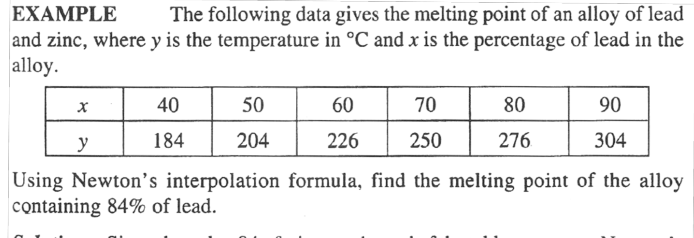

clf ;clear;clc
x = [40 50 60 70 80 90 ]

x =     40    50    60    70    80    90


y=[184 204 226 250 276 304]

y =    184   204   226   250   276   304


[tbl,yi] = Dividediff(x,y,84)

tbl = 1.0e+02 *

   0.400000000000000   1.840000000000000   0.020000000000000   0.000100000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
   0.500000000000000   2.040000000000000   0.022000000000000   0.000100000000000   0.000000000000000  -0.000000000000000                   0
   0.600000000000000   2.260000000000000   0.024000000000000   0.000100000000000  -0.000000000000000                   0                   0
   0.700000000000000   2.500000000000000   0.026000000000000   0.000100000000000                   0                   0                   0
   0.800000000000000   2.760000000000000   0.028000000000000                   0                   0                   0                   0
   0.900000000000000   3.040000000000000                   0                   0                   0                   0                   0


yi =      2.869600000000000e+02


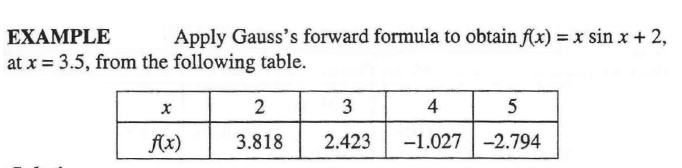

clf ;clear;clc
x = [2 3 4 5]

x =      2     3     4     5


y=[3.818 2.423 -1.027 -2.794]

y =    3.818000000000000   2.423000000000000  -1.027000000000000  -2.794000000000000


tbl= GaussTable(x,y)

tbl =    2.000000000000000   3.818000000000000  -1.395000000000000  -2.055000000000000   3.738000000000000
   3.000000000000000   2.423000000000000  -3.450000000000000   1.683000000000000                   0
   4.000000000000000  -1.027000000000000  -1.767000000000000                   0                   0
   5.000000000000000  -2.794000000000000                   0                   0                   0



% be careful
% set config
h=x(2)-x(1);
x0=x(2);

p = (3.5-x0)/h

p =    0.500000000000000



yp = tbl(2,2) + p*tbl(2,3) + ((p*(p-1))/factorial(2))*tbl(1,4) + (((p+1)*p*(p-1))/factorial(3))*tbl(1,5)

yp =    0.721250000000000
